# Electricity Usage Prediction

Predict electricity usage for 1 July, 2021 for residential sector using quadratic polynomial.

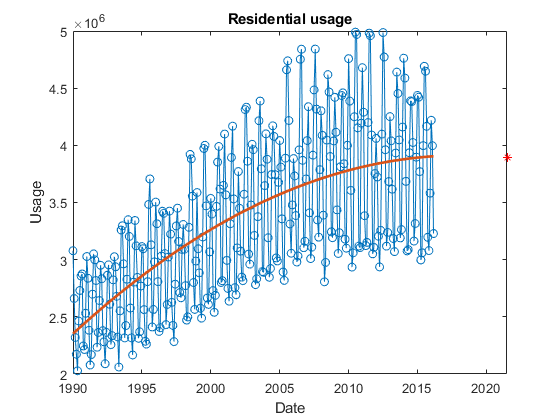

filename_res = 'elec_res.csv';
predictdate1 = datetime(2021,07,01);
res_predictedusage = polyPrediction(filename_res,predictdate1,2);

Predict electricity usage for 1 December, 2020 for residential sector using quartic polynomial.

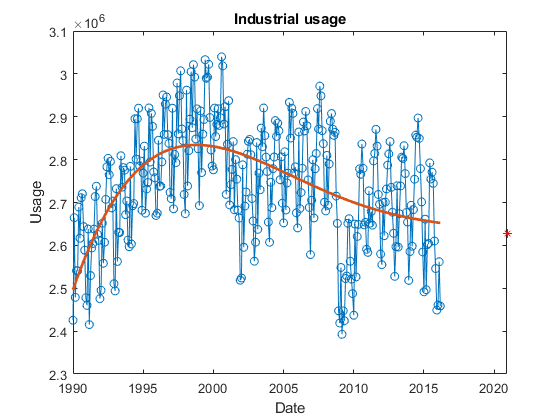

filename_ind = 'elec_ind.csv';
predictdate2 = datetime(2020,12,01);
ind_predictedusage = polyPrediction(filename_ind,predictdate2,4);

### Local function: `polyPrediction`

Fits data with polynomial model, plots data & model, and predicts future usage.

**Inputs**: data filename (text), prediction date (datetime), polynomial degree (integer)

**Outputs**: predicted usage, plot with data + fitted polynomial model

function predictedusage = polyPrediction(filename,predictdate,degree)
    % Import data
    data = readtable(filename);
    dates = data{:,1};
    usage = data{:,2};
    sector = data.Properties.VariableNames{2};
    
    % Fill in the missing values.
    usage = fillmissing(usage,'spline');
    
    % Fit polynomial and predict usage for a future date.
    elapsedYears = years(dates-dates(1));
    c = polyfit(elapsedYears,usage,degree);
    
    endDuration = years(predictdate-dates(1));
    usageFit = polyval(c,elapsedYears);
    predictedusage = polyval(c,endDuration);
    
    % Plot the predicted usage.
    plot(dates,usage,'o-')
    hold on
    plot(dates,usageFit,'LineWidth',2);
    plot(predictdate,predictedusage,'*r');
    hold off
    xlabel('Date')
    ylabel('Usage')
    title([sector ' usage'])
end